clear all
clf
% first manually delete tab References
v = 'valentia.xlsx';

s = readtable (v); % reading data from the specific Data File

%%%%% to delete this? : d = datenum(s.Date, 'yyyy-mm-dd'); % converting date to machine readable serial code

%%% sort the data by date: %%%
allDates=s.Date(:); % gives all dates in one cell
A = datetime(allDates,'Format','yyyy-MM-dd') % formats 'allDates' cell to an array datetime values

A = 708×1 datetime array
   1973-08-15
   1973-07-15
   1973-06-15
   1973-05-15
   1973-04-15
   1973-03-15
   1973-02-15
   1973-01-15
   1972-12-15
   1972-11-15
   1972-10-15
   1972-09-15
   1972-08-15
   1972-07-15
   1972-06-15
   1972-05-15
   1972-04-15
   1972-03-15
   1972-02-15
   1972-01-15
   1971-12-15
   1971-11-15
   1971-10-15
   1975-08-15
   1975-07-15
   1975-06-15
   1975-05-15
   1975-04-15
   1975-03-15
   1975-02-15
   1975-01-15
   1974-12-15
   1974-11-15
   1973-09-15
   1976-05-15
   1976-04-15
   1976-03-15
   1976-02-15
   1976-01-15
   1975-12-15
   1975-11-15
   1975-10-15
   1975-09-15
   1974-10-15
   1974-09-15
   1974-08-15
   1974-07-15
   1974-06-15
   1974-05-15
   1974-04-15
   1974-03-15
   1974-02-15
   1974-01-15
   1973-12-15
   1973-11-15
   1973-10-15
   1971-09-15
   1971-08-15
   1971-07-15
   1971-06-15
   1971-05-15
   1971-04-15
   1971-03-15
   1971-02-15
   1971-01-15
   1970-12-15
   1970-11-15
   1970-10-15
   1970-09-15
   1970-0


[sortDates,originalIndex]=sort(A) %sorts A array (708x1 - includes only dates) into ascending order.

sortDates = 708×1 datetime array
   1957-01-15
   1957-02-15
   1957-03-15
   1957-04-15
   1957-05-15
   1957-06-15
   1957-07-15
   1957-08-15
   1957-09-15
   1957-10-15
   1957-11-15
   1957-12-15
   1958-01-15
   1958-02-15
   1958-03-15
   1958-04-15
   1958-05-15
   1958-06-15
   1958-07-15
   1958-08-15
   1958-09-15
   1958-10-15
   1958-11-15
   1958-12-15
   1959-01-15
   1959-02-15
   1959-03-15
   1959-04-15
   1959-05-15
   1959-06-15
   1959-07-15
   1959-08-15
   1959-09-15
   1959-10-15
   1959-11-15
   1959-12-15
   1960-01-15
   1960-02-15
   1960-03-15
   1960-04-15
   1960-05-15
   1960-06-15
   1960-07-15
   1960-08-15
   1960-09-15
   1960-10-15
   1960-11-15
   1960-12-15
   1961-01-15
   1961-02-15
   1961-03-15
   1961-04-15
   1961-05-15
   1961-06-15
   1961-07-15
   1961-08-15
   1961-09-15
   1961-10-15
   1961-11-15
   1961-12-15
   1962-01-15
   1962-02-15
   1962-03-15
   1962-04-15
   1962-05-15
   1962-06-15
   1962-07-15
   1962-08-15
   1962-09-15
 

originalIndex =    233
   232
   231
   230
   229
   228
   227
   226
   225
   224


                                  %originalIndex gives the original index or s table

sortedS=s(originalIndex,:) %print s table with originalIndex, which gives data in ascending date

sortedS = 708×26 table
    Group        Project                  Site              Country     WMOCode     Latitude    Longitude    Altitude                 TypeOfSite                   SourceOfInformation      SampleName                         MediaType                              Date        BeginOfPeriod    EndOfPeriod     Comment      O18                      O18Provider                       H2                        H2Provider                      H3      H3Error                 H3Provider                 Precipitation    AirTemperature    VapourPressur

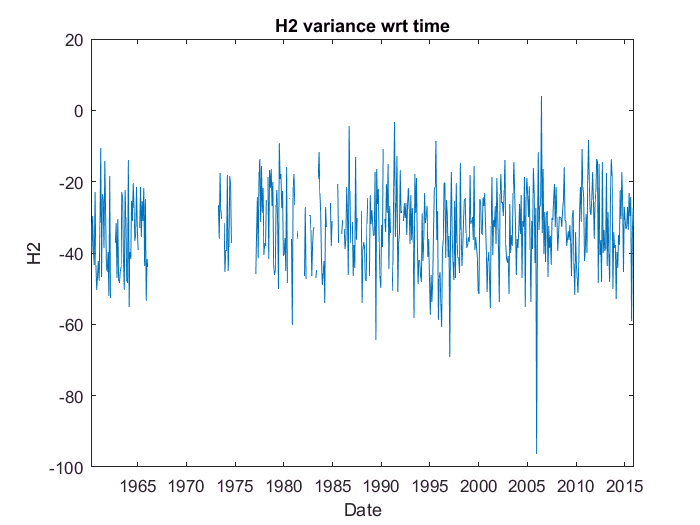


% convenient labelling of variables
H3 = sortedS.H3;
H2 = sortedS. H2;
O18 = sortedS.O18;

figure (1)
plot (sortDates, H2);
datetick('x','yyyy','keeplimits');
xlabel ('Date');
ylabel ('H2');
title ('H2 variance wrt time')

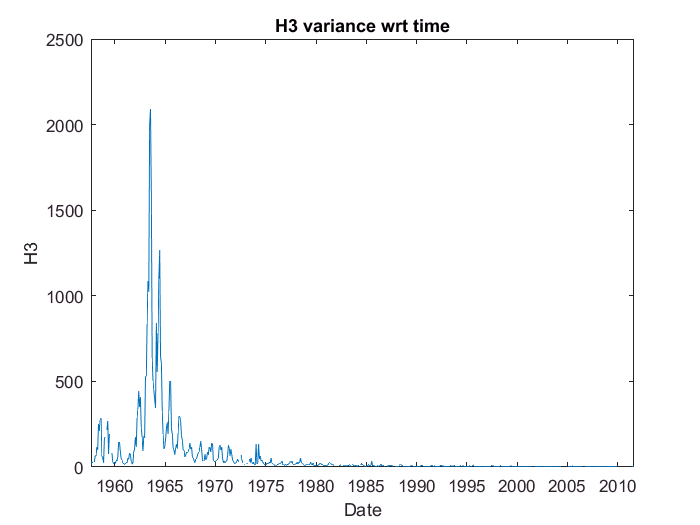


figure (2)
plot (sortDates, H3);
datetick('x','yyyy','keeplimits');
xlabel ('Date');
ylabel ('H3');
title ('H3 variance wrt time')

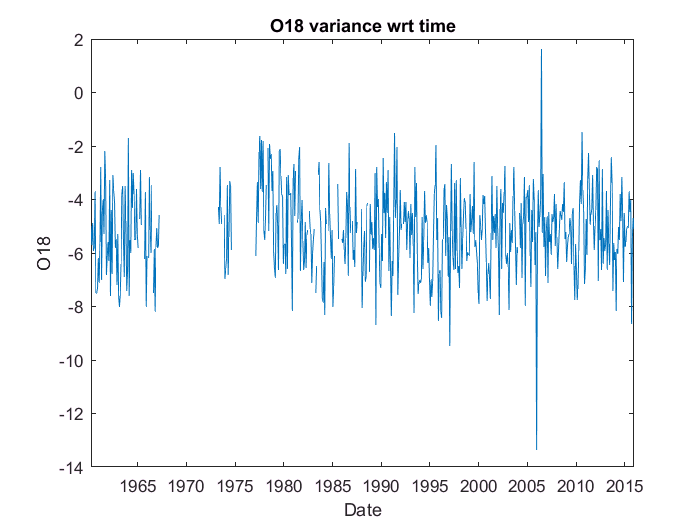


figure (3)
plot (sortDates, O18);
datetick('x','yyyy','keeplimits');
xlabel ('Date');
ylabel ('O18');
title ('O18 variance wrt time')